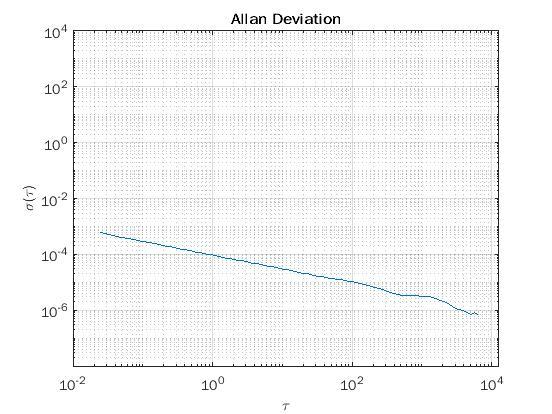

% IMU Data of 5 Hours and Analysis:

s = rosbag("Lab3Long1.bag");
imu = select(s, "Topic", "imu/imu_data");
%mag = select(s, "Topic", "imu/magnetic_data");
imu_msgs = readMessages(imu,"DataFormat","struct");
%mag_msgs = readMessages(mag,"DataFormat","struct");
% imu_msgs{1}
% mag_msgs{1}

% THE ANALYSIS WAS DONE ONE AXIS AT A TIME AND SO THE OTHER VALUES ARE
% COMMENTED IN ORDER TO REDUCE THE PROCESSING SPEED

%imu_seq = cellfun(@(m) double(m.Header.Seq),imu_msgs);
%imu_qx = cellfun(@(m) double(m.Orientation.X),imu_msgs);
%imu_qy = cellfun(@(m) double(m.Orientation.Y),imu_msgs);
%imu_qz = cellfun(@(m) double(m.Orientation.Z),imu_msgs);
%imu_qw = cellfun(@(m) double(m.Orientation.W),imu_msgs);
%imu_gx = cellfun(@(m) double(m.AngularVelocity.X),imu_msgs);
%imu_gy = cellfun(@(m) double(m.AngularVelocity.Y),imu_msgs);
imu_gz = cellfun(@(m) double(m.AngularVelocity.Z),imu_msgs);
%imu_ax = cellfun(@(m) double(m.LinearAcceleration.X),imu_msgs);
%imu_ay = cellfun(@(m) double(m.LinearAcceleration.Y),imu_msgs);
%imu_az = cellfun(@(m) double(m.LinearAcceleration.Z),imu_msgs);

%mag_seq = cellfun(@(m) double(m.Header.Seq),mag_msgs);
%mag_x = cellfun(@(m) double(m.MagneticField_.X),mag_msgs);
%mag_y = cellfun(@(m) double(m.MagneticField_.Y),mag_msgs);
%mag_z = cellfun(@(m) double(m.MagneticField_.Z),mag_msgs);
%{
mean_imu_ax = mean(imu_ax)
mean_imu_ay = mean(imu_ay)
mean_imu_az = mean(imu_az)
std_imu_ax = std(imu_ax)
std_imu_ay = std(imu_ay)
std_imu_az = std(imu_az)

mean_imu_gx = mean(imu_gx)
mean_imu_gy = mean(imu_gy)
mean_imu_gz = mean(imu_gz)
std_imu_gx = std(imu_gx)
std_imu_gy = std(imu_gy)
std_imu_gz = std(imu_gz)

mean_mag_x = mean(mag_x)
mean_mag_y = mean(mag_y)
mean_mag_z = mean(mag_z)
std_mag_x = std(mag_x)
std_mag_y = std(mag_y)
std_mag_z = std(mag_z)
%}
% Load logged data from one axis of a three-axis gyroscope. This recording
% was done over a five hour period with a 40 Hz sampling rate.
omega = imu_gz;
Fs = 40;
t0 = 1/Fs;

theta = cumsum(omega, 1)*t0;

maxNumM = 100;
L = size(theta, 1);
maxM = 2.^floor(log2(L/2));
m = logspace(log10(1), log10(maxM), maxNumM).';
m = ceil(m); % m must be an integer.
m = unique(m); % Remove duplicates.

tau = m*t0;

avar = zeros(numel(m), 1);
for i = 1:numel(m)
    mi = m(i);
    avar(i,:) = sum( ...
        (theta(1+2*mi:L) - 2*theta(1+mi:L-mi) + theta(1:L-2*mi)).^2, 1);
end
avar = avar ./ (2*tau.^2 .* (L - 2*m));

adev = sqrt(avar);

figure
loglog(tau, adev)
title('Allan Deviation')
xlabel('\tau');
ylabel('\sigma(\tau)')
grid on
axis equal

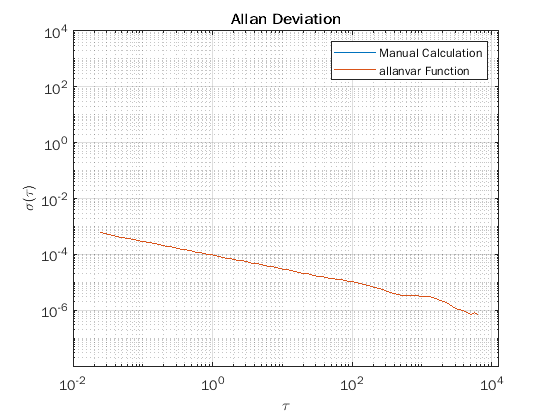


[avarFromFunc, tauFromFunc] = allanvar(omega, m, Fs);
adevFromFunc = sqrt(avarFromFunc);

figure
loglog(tau, adev, tauFromFunc, adevFromFunc);
title('Allan Deviation')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('Manual Calculation', 'allanvar Function')
grid on
axis equal


% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = -0.5;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the angle random walk coefficient from the line.
logN = slope*log(1) + b;
N = 10^logN

N = 9.3382e-05

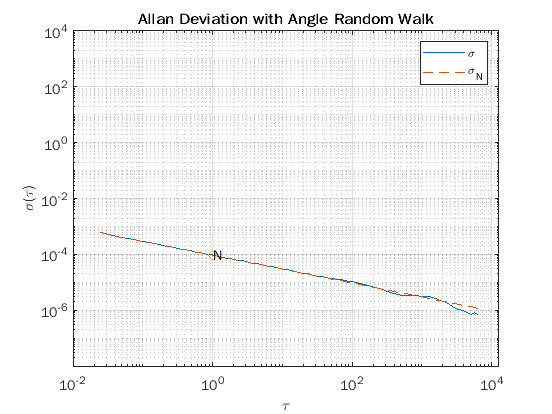


% Plot the results.
tauN = 1;
lineN = N ./ sqrt(tau);
figure
loglog(tau, adev, tau, lineN, '--', tauN, N, 'o')
title('Allan Deviation with Angle Random Walk')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_N')
text(tauN, N, 'N')
grid on
axis equal


% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = 0.5;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the rate random walk coefficient from the line.
logK = slope*log10(3) + b;
K = 10^logK

K = 2.4189e-07

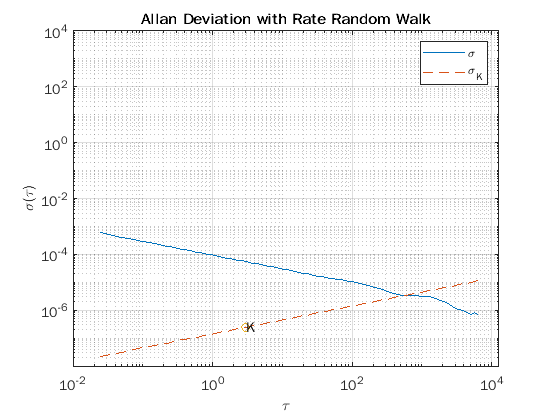


% Plot the results.
tauK = 3;
lineK = K .* sqrt(tau/3);
figure
loglog(tau, adev, tau, lineK, '--', tauK, K, 'o')
title('Allan Deviation with Rate Random Walk')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_K')
text(tauK, K, 'K')
grid on
axis equal


% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = 0;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the bias instability coefficient from the line.
scfB = sqrt(2*log(2)/pi);
logB = b - log10(scfB);
B = 10^logB

B = 5.1404e-06

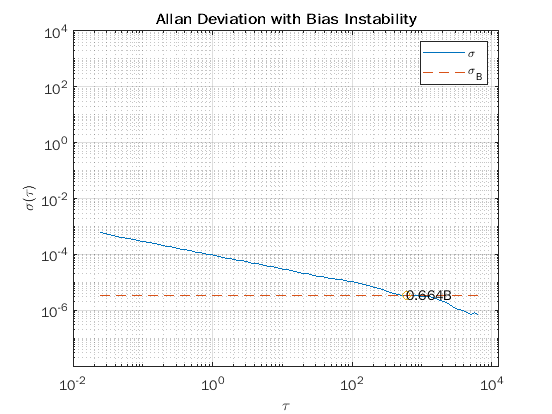


% Plot the results.
tauB = tau(i);
lineB = B * scfB * ones(size(tau));
figure
loglog(tau, adev, tau, lineB, '--', tauB, scfB*B, 'o')
title('Allan Deviation with Bias Instability')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_B')
text(tauB, scfB*B, '0.664B')
grid on
axis equal

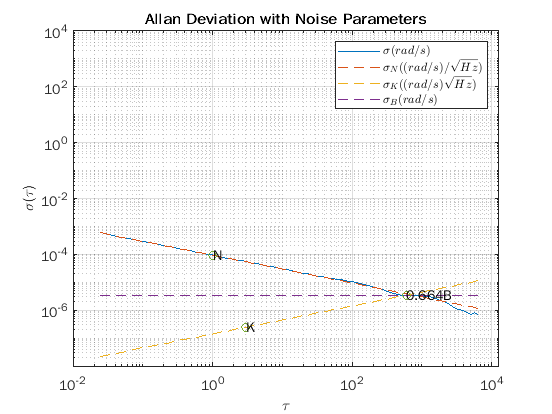


tauParams = [tauN, tauK, tauB];
params = [N, K, scfB*B];
figure
loglog(tau, adev, tau, [lineN, lineK, lineB], '--', ...
    tauParams, params, 'o')
title('Allan Deviation with Noise Parameters')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('$\sigma (rad/s)$', '$\sigma_N ((rad/s)/\sqrt{Hz})$', ...
    '$\sigma_K ((rad/s)\sqrt{Hz})$', '$\sigma_B (rad/s)$', 'Interpreter', 'latex')
text(tauParams, params, {'N', 'K', '0.664B'})
grid on
axis equal

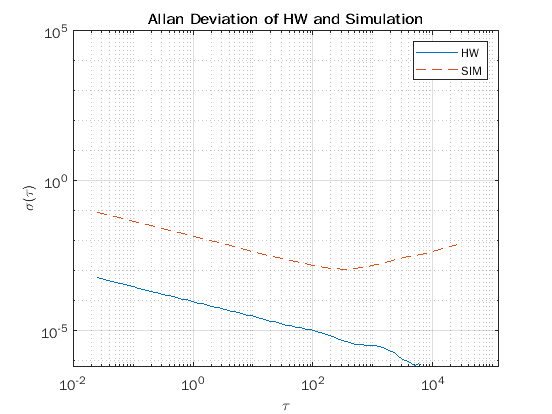


% Simulating the gyroscope measurements takes some time. To avoid this, the
% measurements were generated and saved to a MAT-file. By default, this
% example uses the MAT-file. To generate the measurements instead, change
% this logical variable to true.
generateSimulatedData = false;

if generateSimulatedData
    % Set the gyroscope parameters to the noise parameters determined
    % above.
    gyro = gyroparams('NoiseDensity', N, 'RandomWalk', K, ...
        'BiasInstability', B);
    omegaSim = helperAllanVarianceExample(L, Fs, gyro);
else
    load('SimulatedSingleAxisGyroscope', 'omegaSim')
end

[avarSim, tauSim] = allanvar(omegaSim, 'octave', Fs);
adevSim = sqrt(avarSim);
adevSim = mean(adevSim, 2); % Use the mean of the simulations.

figure
loglog(tau, adev, tauSim, adevSim, '--')
title('Allan Deviation of HW and Simulation')
xlabel('\tau');
ylabel('\sigma(\tau)')
legend('HW', 'SIM')
grid on
axis equal